# [5.10. Дифракция](https://ru.wikipedia.org/wiki/Дифракция)

#### Формула Кирхгофа для вклада от элемента поверхности dA фронта волны в поле в точке P

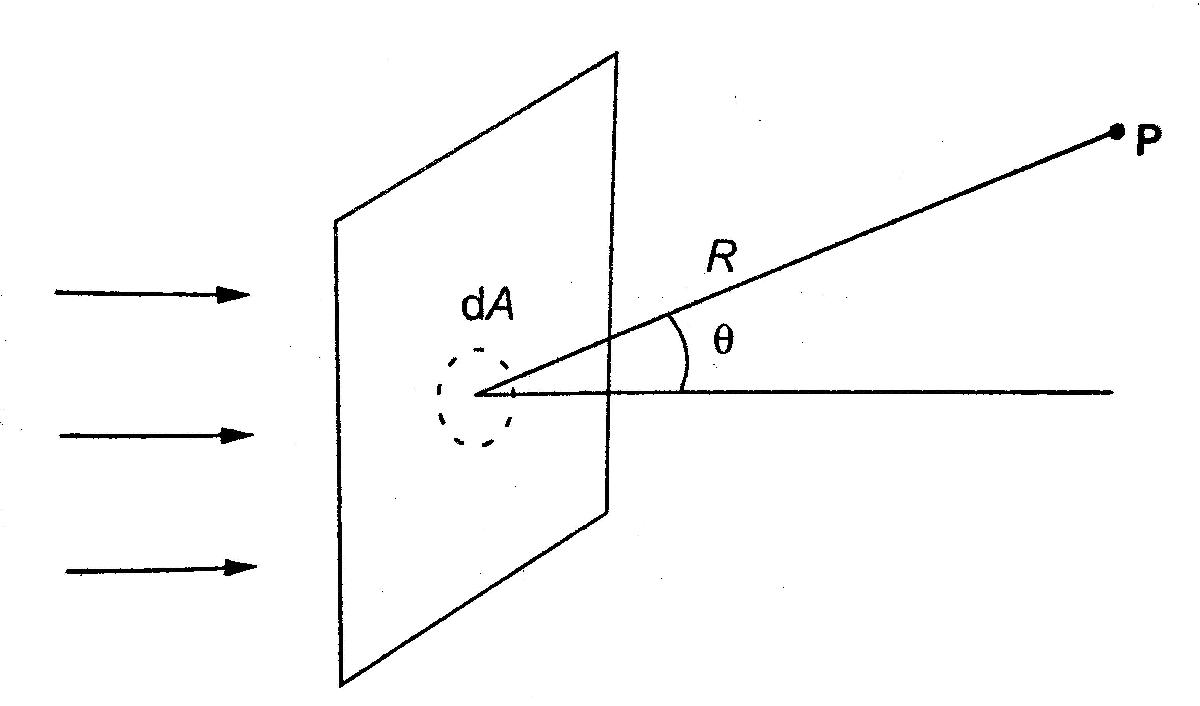

syms dpsi a omega k R theta A t dA lambda
dpsi=a*exp(i*omega*t)*exp(-i*k*R)/R*(1+cos(theta))/2*dA

$$dpsi = \frac{a\,\mathrm{dA}\,{\mathrm{e}}^{-R\,k\,\mathrm{i}}\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}\,\left(\cos\left(\theta \right)+1\right)}{2\,R}$$

% a = const
k==2*pi/lambda

$$ans = k=\frac{2\,\pi }{\lambda }$$

#### Интенсивность в случае [дифракции Фраунгофера](https://ru.wikipedia.org/wiki/Дифракция_Фраунгофера) на одной щели (нормальное падение)

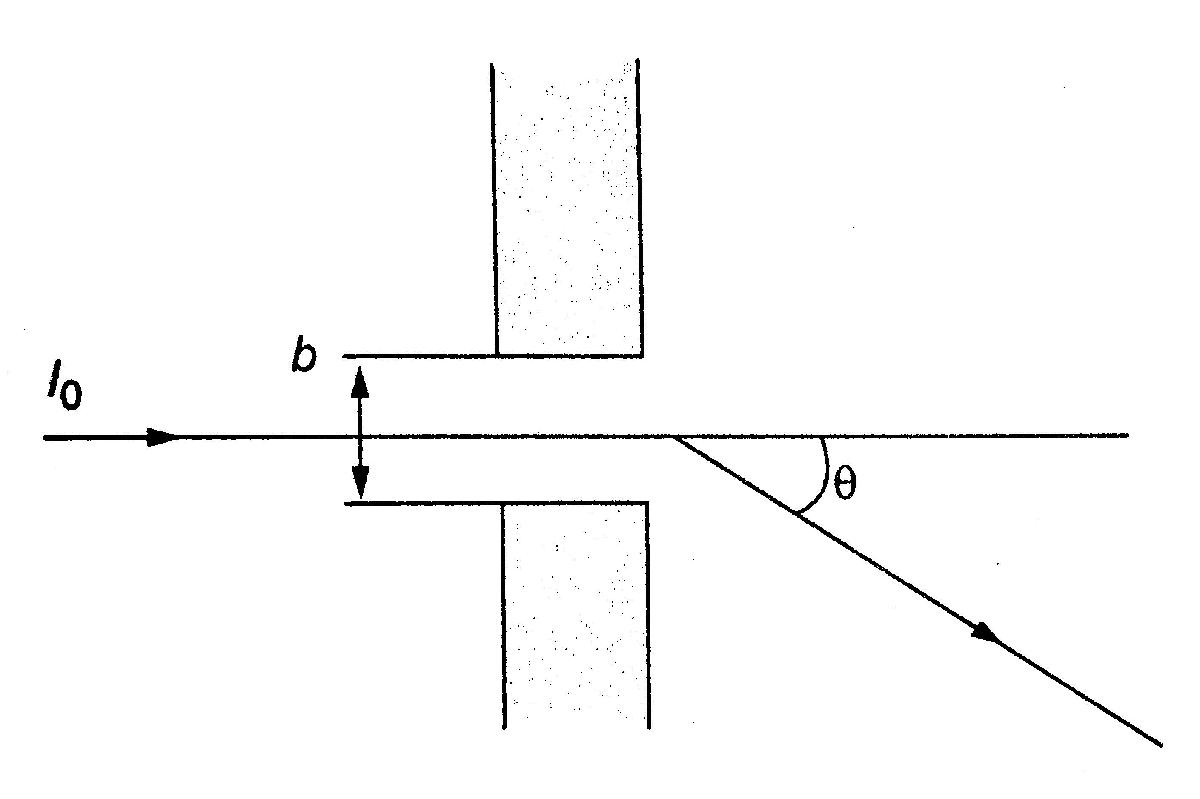

syms I I0 beta b
I==I0*(sin(beta/2)/(beta/2))^2

$$ans = \text{I}=\frac{4\,I_{0}\,{\sin\left(\frac{\beta }{2}\right)}^{2}}{\beta^{2}}$$

beta=2*pi/lambda*b*sin(theta)

$$beta = \frac{2\,\pi \,b\,\sin\left(\theta \right)}{\lambda }$$

Условие минимумов интенсивности

syms theta m lambda
b*sin(theta)==m*lambda        % m=+-1,+-2,...

$$ans = b\,\sin\left(\theta \right)=\lambda \,m$$

Разрешающая способность по Рэлею

syms phi_r lambda b
sin(phi_r)==lambda/b

$$ans = \sin\left(\varphi_{r}\right)=\frac{\lambda }{b}$$

#### Угол theta_m первого минимума дифракции на круглом отверстии диаметра D

syms theta_m lambda D
sin(theta_m)==vpa(1.22)*lambda/D

$$ans = \sin\left(\theta_{m}\right)=\frac{1.22\,\lambda }{\text{D}}$$

Предел разрешения по Рэлею

phi_r==theta_m

$$ans = \varphi_{r}=\theta_{m}$$

#### Площадь зоны Френеля при дифракции Френеля

syms A d lambda
A=pi*d*lambda

$$A = \pi \,d\,\lambda$$

% d = расстояние от центра до отверстия

Условие экстремума интенсивности

syms r m lambda d
r^2==m*lambda*d

$$ans = r^{2}=d\,\lambda \,m$$

% m=1,3,5,... => I=4*I0
% m=2,4,6,... => I=0

#### Дифракция Фраунгофера на N щелях при нормальном падении

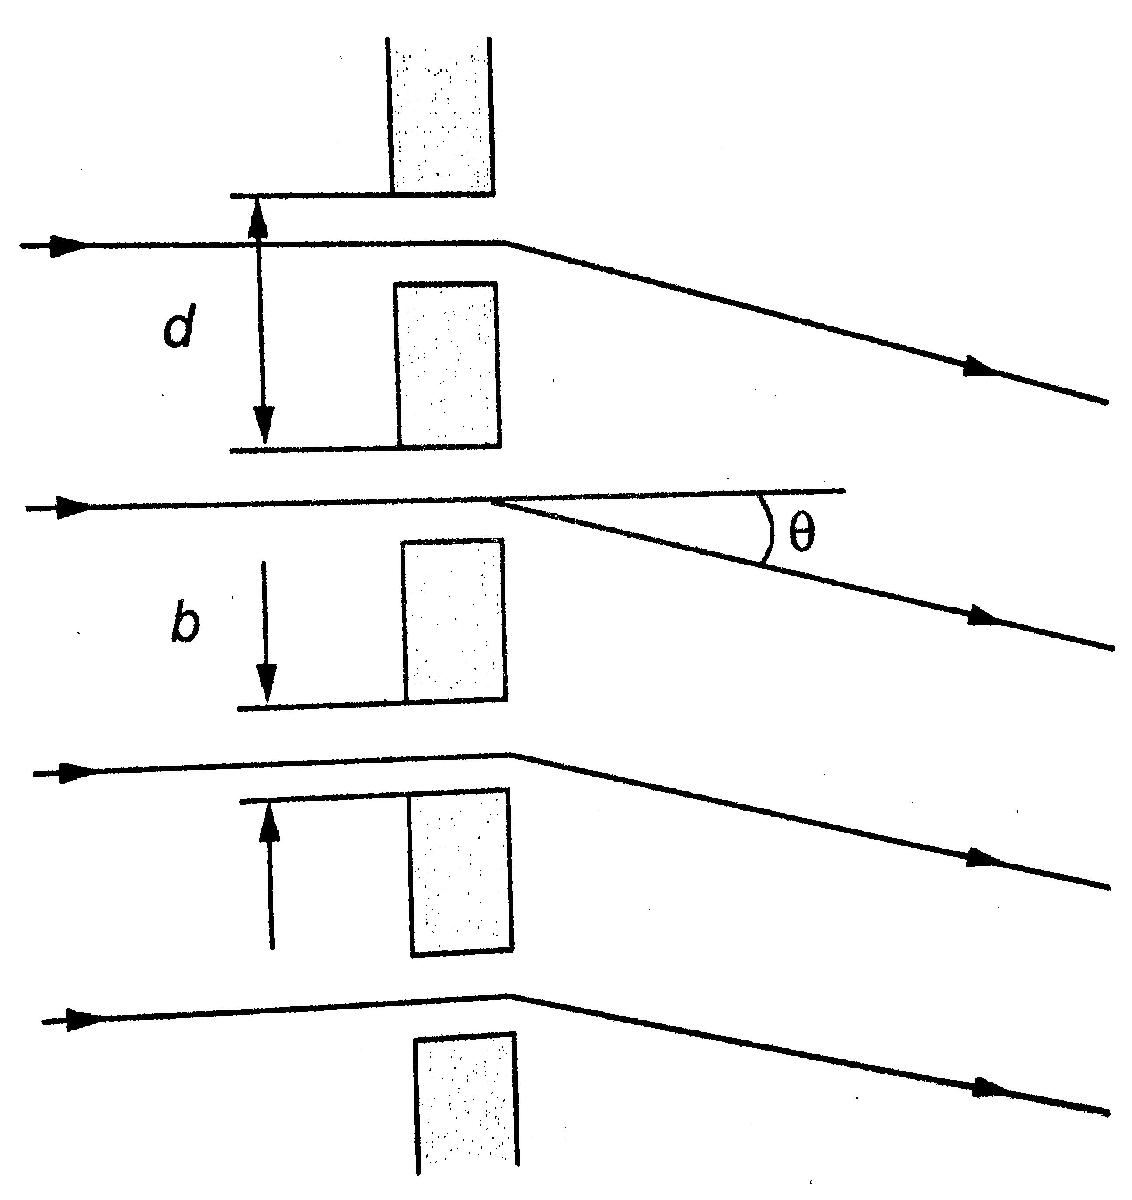

syms I I0 beta N delta
I=I0*(sin(beta/2)/(beta/2))^2*(sin(N*delta/2)/sin(delta/2))^2

$$I = \frac{4\,I_{0}\,{\sin\left(\frac{\beta }{2}\right)}^{2}\,{\sin\left(\frac{N\,\delta }{2}\right)}^{2}}{\beta^{2}\,{\sin\left(\frac{\delta }{2}\right)}^{2}}$$

beta==2*pi/lambda*b*sin(theta)

$$ans = \beta =\frac{2\,\pi \,b\,\sin\left(\theta \right)}{\lambda }$$

delta==2*pi/lambda*d*sin(theta)

$$ans = \delta =\frac{2\,\pi \,d\,\sin\left(\theta \right)}{\lambda }$$

% d = постоянная решетки

Условие интерференционного максимума (формула решетки)

d*sin(theta)==m*lambda    % m=0,+-1,+-2,...

$$ans = d\,\sin\left(\theta \right)=\lambda \,m$$

Условие дифракционного минимума

b*sin(theta)==m*lambda   % m=+-1,+-2,...

$$ans = b\,\sin\left(\theta \right)=\lambda \,m$$

#### Формула решетки при наклонном падении

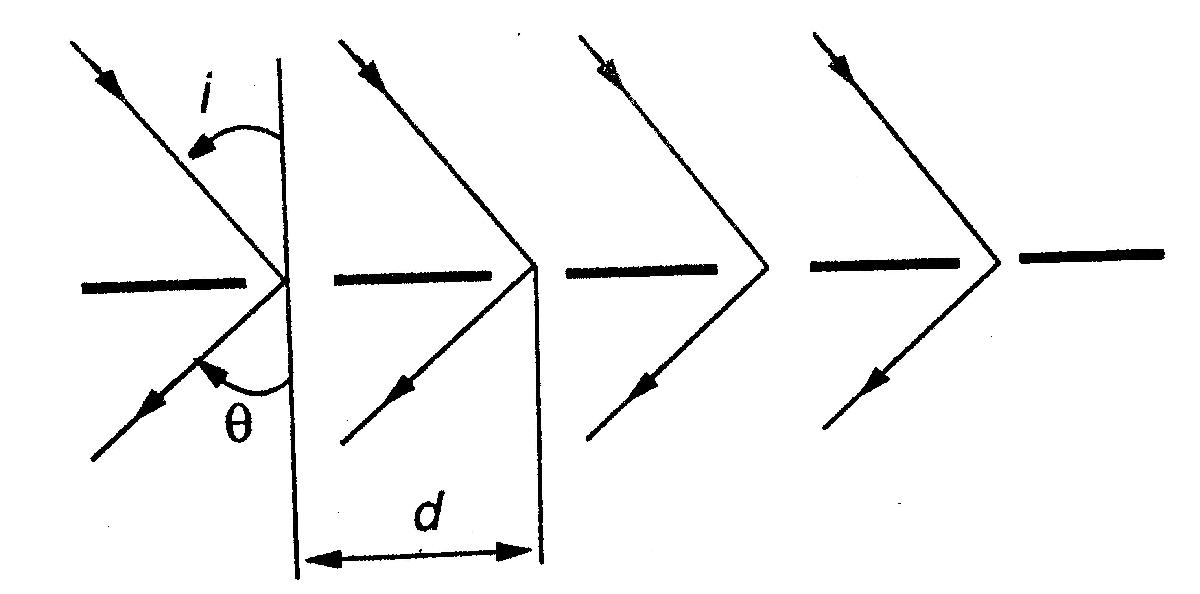

syms d theta i m lambda
d*(sin(theta)+sin(i))==m*lambda    % m=0,+-1,+-2,...

$$ans = d\,\left(\sin\left(i\right)+\sin\left(\theta \right)\right)=\lambda \,m$$

Для отражательных дифракционных решеток

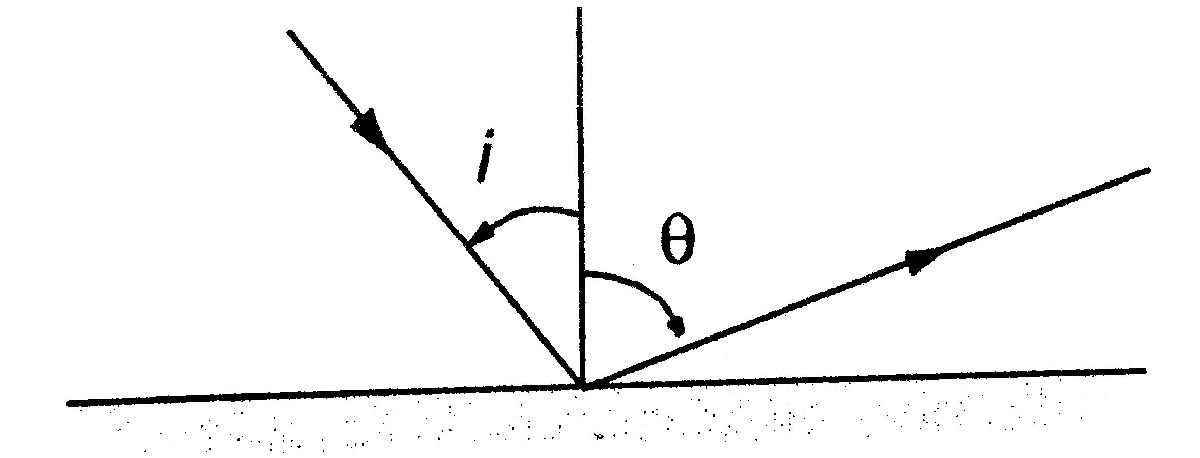

d*(sin(theta)-sin(i))==m*lambda    % m=0,+-1,+-2,...

$$ans = -d\,\left(\sin\left(i\right)-\sin\left(\theta \right)\right)=\lambda \,m$$

#### [Закон Брэгга](https://ru.wikipedia.org/wiki/Условие_Вульфа_—_Брэгга) (условие интерференционного максимума)

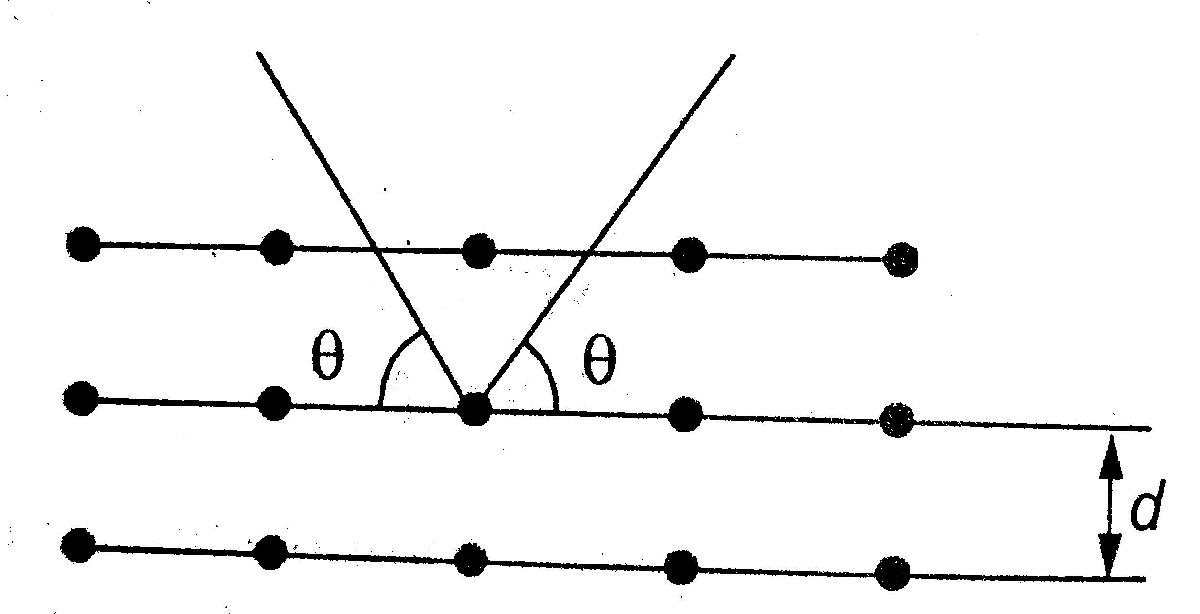

2*d*sin(theta)==m*lambda    % m=0,1,2,...

$$ans = 2\,d\,\sin\left(\theta \right)=\lambda \,m$$

#### Разрешающая способность и угловая дисперсия дифракционных решеток

syms Delta(x) theta(lambda)
R==lambda/Delta(lambda)==N*m

$$ans = \left(R=\frac{\lambda }{\Delta \left(\lambda \right)}\right)=N\,m$$

D==diff(theta,lambda)==m/(d*cos(theta))

$$ans(lambda) = \left(\text{D}=\frac{\partial }{\partial \lambda }\theta \left(\lambda \right)\right)=\frac{m}{d\,\cos\left(\theta \left(\lambda \right)\right)}$$

% Delta(lambda) = наименьшая разница длин волн двух разрешимых линий